%Decoder

%Assumptions - this will take in input of a 1 x Many matrix of data values
%from the demodulator

%Tasks: 
% % Downsample such that it's back to 16ishkhz - 2080 wide per line
% % Determine where the start of each line is using a correlator
% % Seperate the data into Lines
% % remove the APK metadata, leaving 1818 lines
% % print it as jpeg file


%Sampling:

%Data is modulated at 16kHz originally
%Resample to 16.640khz

%Resample wav data to be 8320 samples per line

current_size =size(z,1);
desired_size = (current_length / 16000) * 16640;

desired_ratio = 16640/16000;
step_per_sample = 1/desired_ratio;

x = 0:current_size-1

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


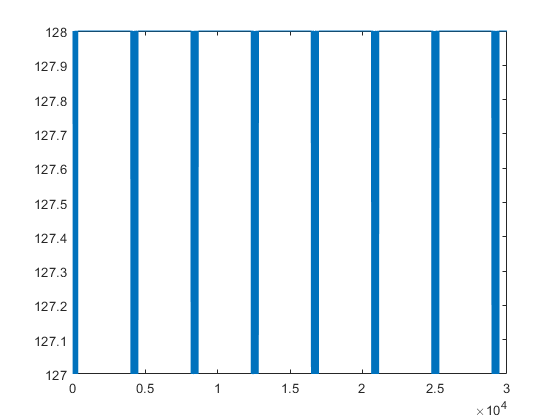

xq = 0:step_per_sample:current_size; %hopefully should define the new query to be four times upsampling

resampled_data = interp1(x,z,xq);


plot(z(1:30000));

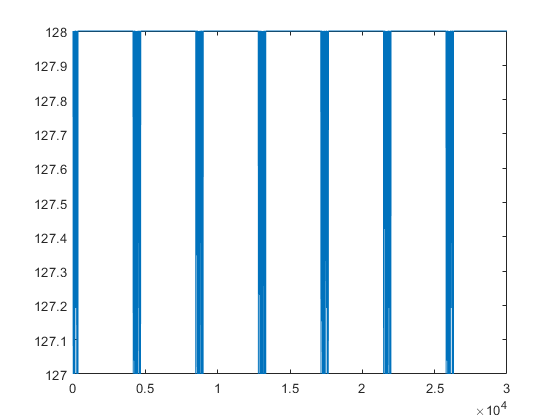

plot(resampled_data(1:30000));

% % Determine where the start of each line is using a correlator
